V0=1;
gamma=2*pi*1i;
z = -2:0.02:0;

GAMMA=0;
Z0=100;
[Vs,Is] = linephasor(V0,GAMMA,gamma,Z0,z); % given formula 
Vs = abs(Vs);
Is = 100*abs(Is);
VSWR = 100*max(Vs)/min(Vs) %given 

VSWR = 100.0000

for z=0 %for calculating ratio 
    ratio = 100*Vs/Is
    z = -2:0.02:0;
end

ratio = 100.0000

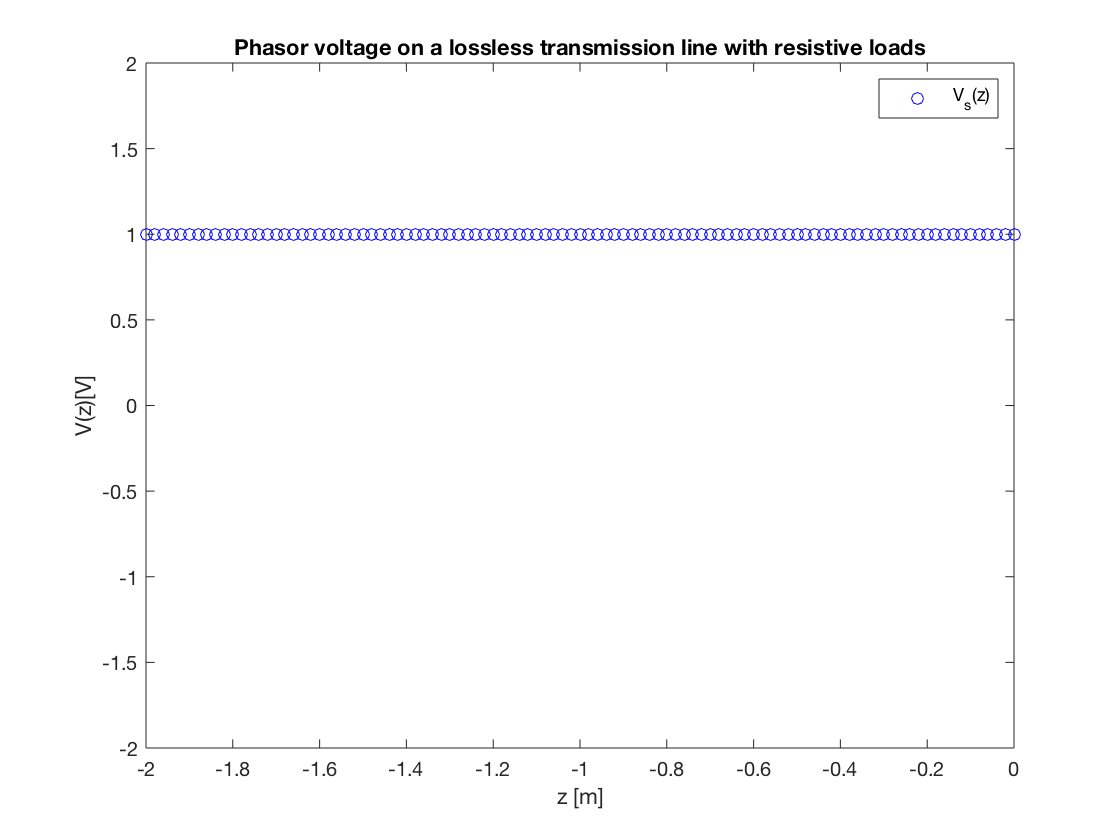

plot(z,Vs,'bo');
xlabel('z [m]');
ylabel('V(z)[V]');
title('Phasor voltage on a lossless transmission line with resistive loads');
legend('V_s(z)');
axis([-2 0 -2 2]);

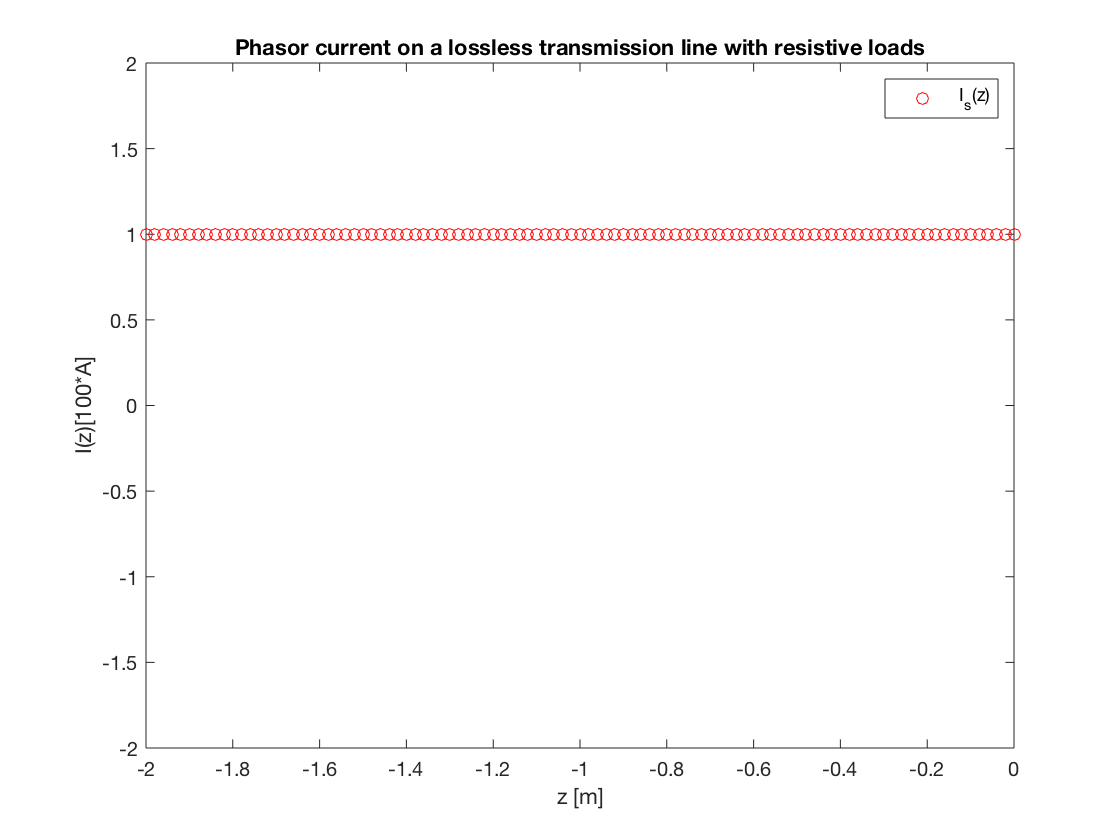

plot(z,Is,'ro');
xlabel('z [m]');
ylabel('I(z)[100*A]');
title('Phasor current on a lossless transmission line with resistive loads');
legend('I_s(z)');
axis([-2 0 -2 2]);


GAMMA=1/3;
Z0=100;
[Vs,Is] = linephasor(V0,GAMMA,gamma,Z0,z);
Vs = abs(Vs);
Is = 100*abs(Is);
VSWR = 100*max(Vs)/min(Vs)

VSWR = 199.7041

for z=0
    ratio = 100*Vs/Is
    z = -2:0.02:0;
end

ratio = 100.0000

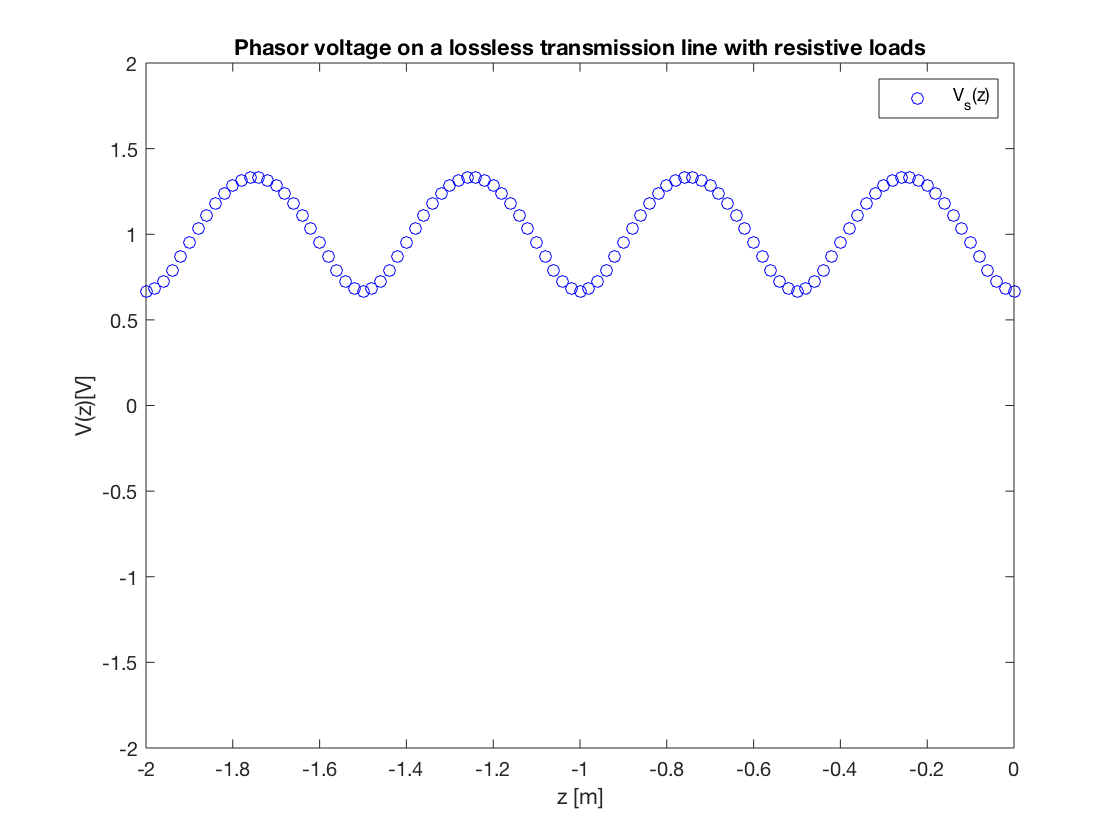

plot(z,Vs,'bo');
xlabel('z [m]');
ylabel('V(z)[V]');
title('Phasor voltage on a lossless transmission line with resistive loads');
legend('V_s(z)');
axis([-2 0 -2 2]);

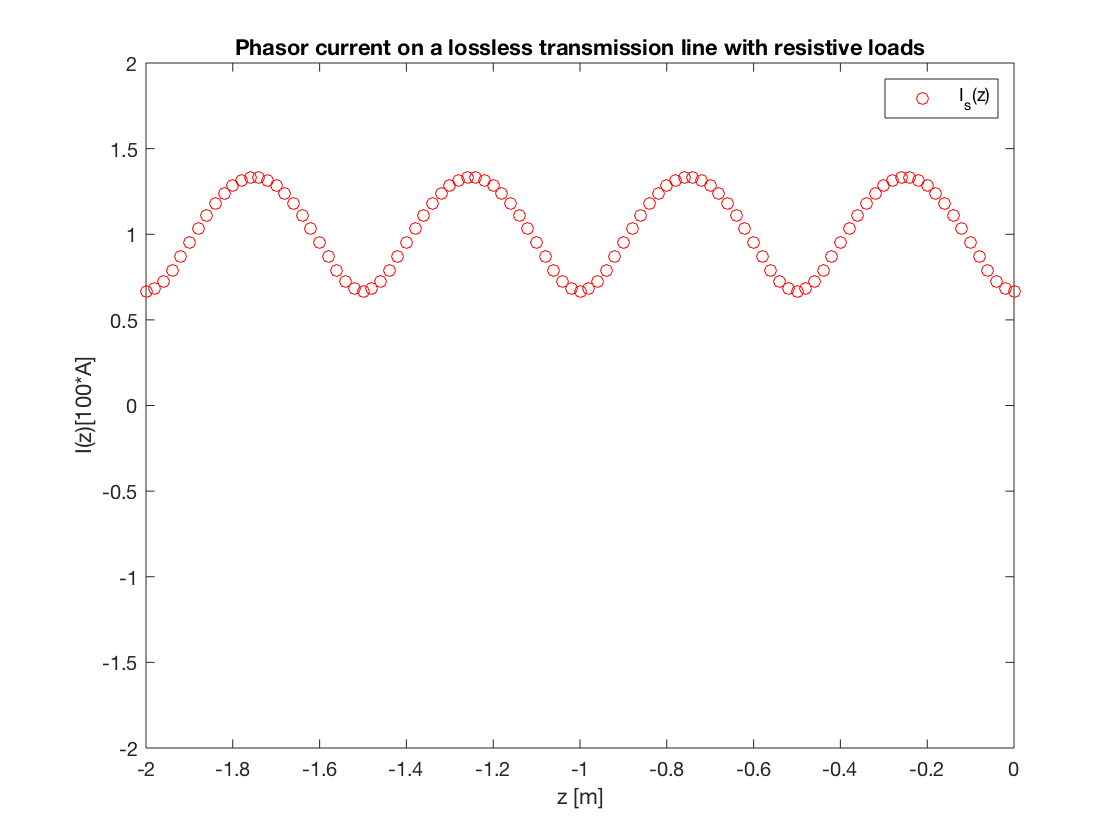

plot(z,Is,'ro');
xlabel('z [m]');
ylabel('I(z)[100*A]');
title('Phasor current on a lossless transmission line with resistive loads');
legend('I_s(z)');
axis([-2 0 -2 2]);


GAMMA=2/3;
Z0=100;
[Vs,Is] = linephasor(V0,GAMMA,gamma,Z0,z);
Vs = abs(Vs);
Is = 100*abs(Is);
VSWR = 100*max(Vs)/min(Vs)

VSWR = 499.0529

for z=0
    ratio = 100*Vs/Is
    z = -2:0.02:0;
end

ratio = 100.0000

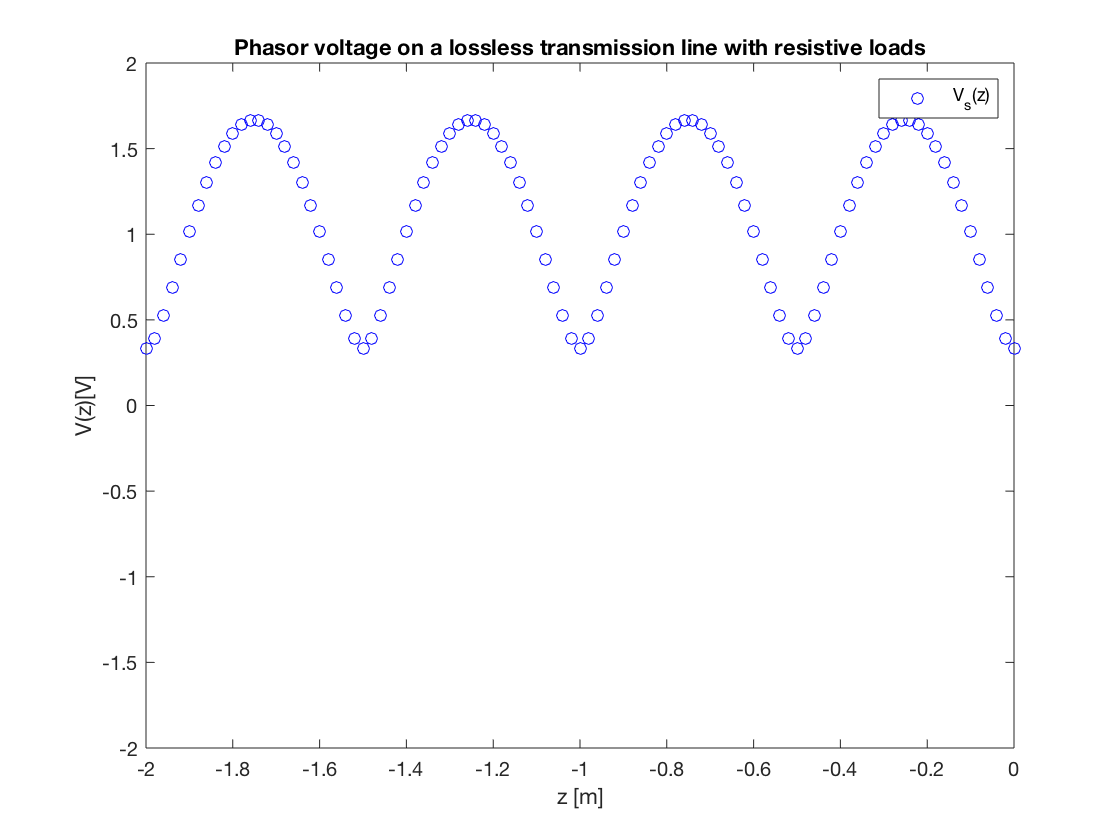

plot(z,Vs,'bo');
xlabel('z [m]');
ylabel('V(z)[V]');
title('Phasor voltage on a lossless transmission line with resistive loads');
legend('V_s(z)');
axis([-2 0 -2 2]);

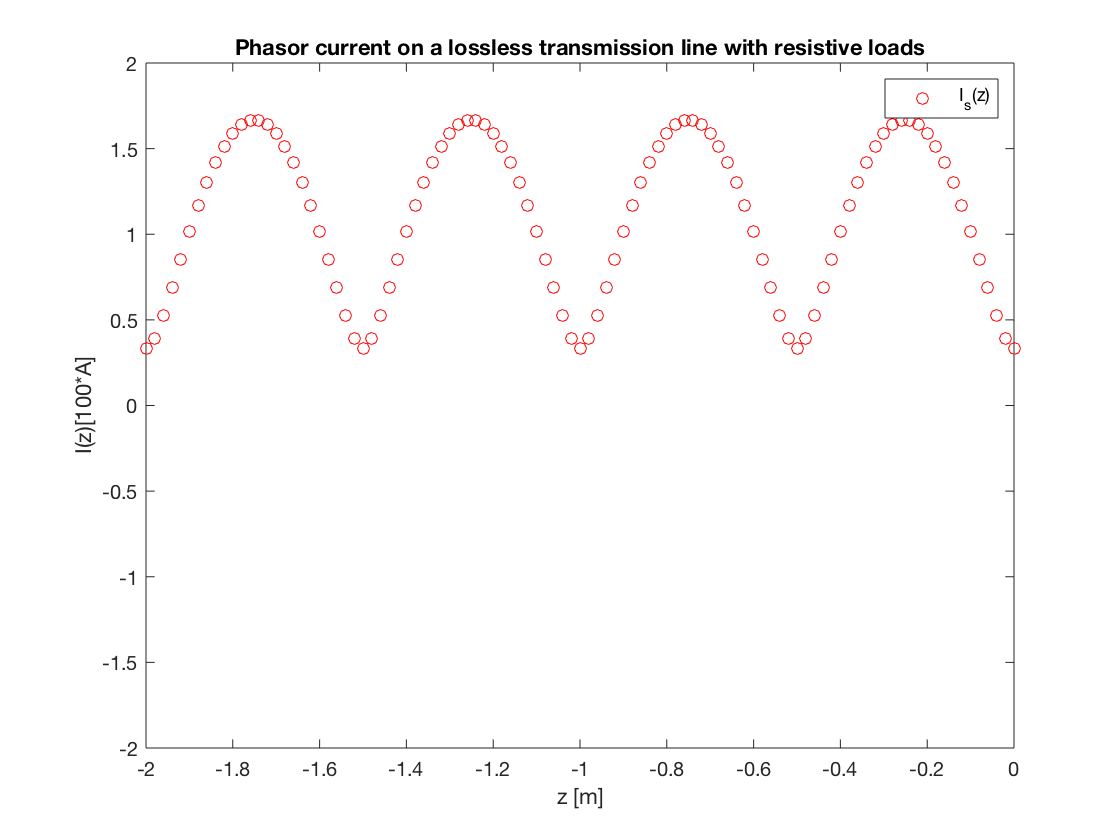

plot(z,Is,'ro');
xlabel('z [m]');
ylabel('I(z)[100*A]');
title('Phasor current on a lossless transmission line with resistive loads');
legend('I_s(z)');
axis([-2 0 -2 2]);


GAMMA=1;
Z0=100;
[Vs,Is] = linephasor(V0,GAMMA,gamma,Z0,z);
Vs = abs(Vs);
Is = 100*abs(Is);
VSWR = 100*max(Vs)/min(Vs)

VSWR = Inf

for z=0
    ratio = 100*Vs./Is
    z = -2:0.02:0;
end

ratio =   100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000


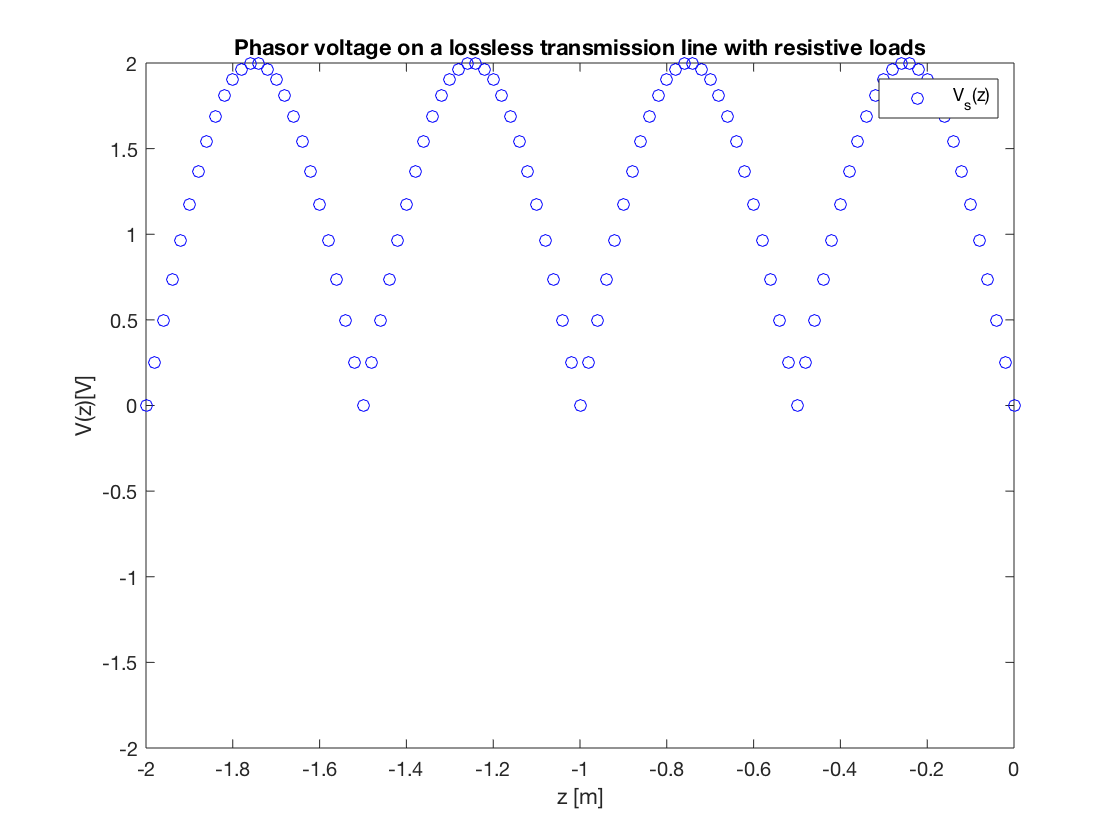

plot(z,Vs,'bo');
xlabel('z [m]');
ylabel('V(z)[V]');
title('Phasor voltage on a lossless transmission line with resistive loads');
legend('V_s(z)');
axis([-2 0 -2 2]);

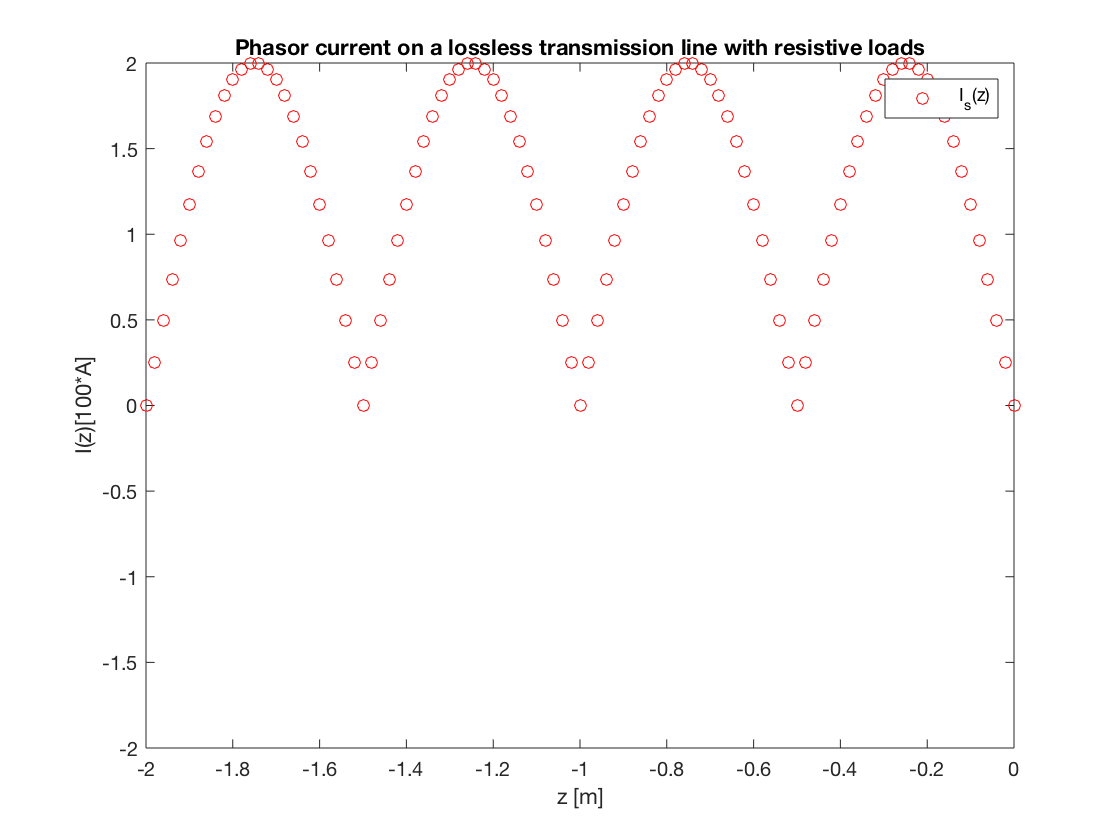

plot(z,Is,'ro');
xlabel('z [m]');
ylabel('I(z)[100*A]');
title('Phasor current on a lossless transmission line with resistive loads');
legend('I_s(z)');
axis([-2 0 -2 2]);

function [Vs,Is] = linephasor(V0,GAMMA,gamma,Z0,z)
Vs = (V0)*exp(-gamma*z) - GAMMA*(V0)*exp(gamma*z); 
Is = (V0/Z0)*exp(-gamma*z) - GAMMA*(V0/Z0)*exp(gamma*z); 
end